# Series de Taylor

Las serie de Taylor es una aproximación polinomial a una función $f(x)=p_n+R_n$ alrededor del punto $x_0\in[a,b]$ dada por la expresión 


$$f(x)=f(x_0)+f'(x_0)(x-x_0)+\frac{f''(x_0)}{2!}(x-x_0)^2+\frac{f'''(x_0)}{3!}(x-x_0)^3+...+\frac{f^{(n)}}{n!}(x-x_0)^n+R_n$$


y donde $R_n$ son los términos restantes de la serie infinita. A este término se le conoce como *residuo *y tiene la forma 


$$R_n(x)=\frac{(x-x_0)^{n+1}}{(n+1)!}f^{(n+1)(\xi)}$$


donde $\xi$ es un punto en el intervalo $[x,x_0]$.

Cuando se calcula numéricamente el factor $R_n$ se acota con por un valor arbitrario. Este valor denota la precisión de la aproximación para el valor $f(x)
$ buscado.

### Ejemplo

Calcular el valor de la función $f(x)=e^x$ alrededor del punto $x_0=0$ en el intervalo $x\in[-1,1]$ con una precisión de $10^{-6}$. Las series de Taylor generada con la condición $x_0=0$ se les conoce como las series de Maclaurin.

La seríe de Taylor de esta función se escribe como:


$$e^x=1+x+\frac{x^2}{2!}+\frac{x^3}{3!}+...+\frac{x^n}{n!}+R_n, \qquad \forall x\in[-1,1]$$


y donde el error $|R_n|=|e^x-p_n|$ se puede acotar considerando $|R_n|\leq\frac{e}{(n+1)!}\leq10^{-6}$, desigualdad que se cumple para $n=9$. Por lo tanto la serie de Taylor debe tener nueve términos, es decir es una aproximación de ***9° orden *** tiene los términos 


$$e^x=\sum_{k=0}^9\,\frac{x^k}{k!}$$


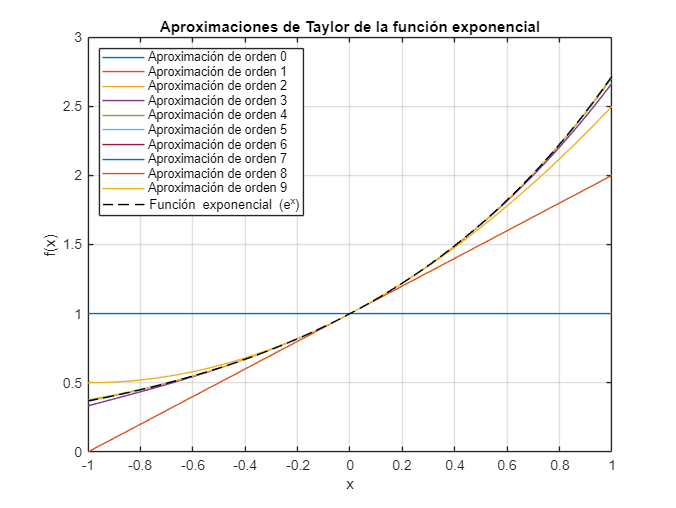

% Cálculo y graficación de la serie de Taylor de la función exponencial

% Definir el intervalo
x = linspace(-1, 1, 100);

% Definir el error máximo permitido
error_max = 1e-6;

% Definir el número de términos (n=9)
n = 9;

% Inicializar la figura principal
figure;

% Calcular y graficar las aproximaciones de Taylor
for i = 0:n
    % Calcular la aproximación de Taylor de orden i
    taylor_aprox = zeros(size(x));
    for k = 0:i
        taylor_aprox = taylor_aprox + (x.^k) / factorial(k);
    end
    
    % Graficar la aproximación
    plot(x, taylor_aprox, 'DisplayName', sprintf('Aproximación de orden %d', i));
    hold on;
end

% Graficar la función exponencial original
plot(x, exp(x), 'k--', 'DisplayName', 'Función exponencial (e^x)');

% Añadir etiquetas y leyenda a la figura principal
xlabel('x');
ylabel('f(x)');
title('Aproximaciones de Taylor de la función exponencial');
legend('Location', 'northwest');
grid on;
hold off;

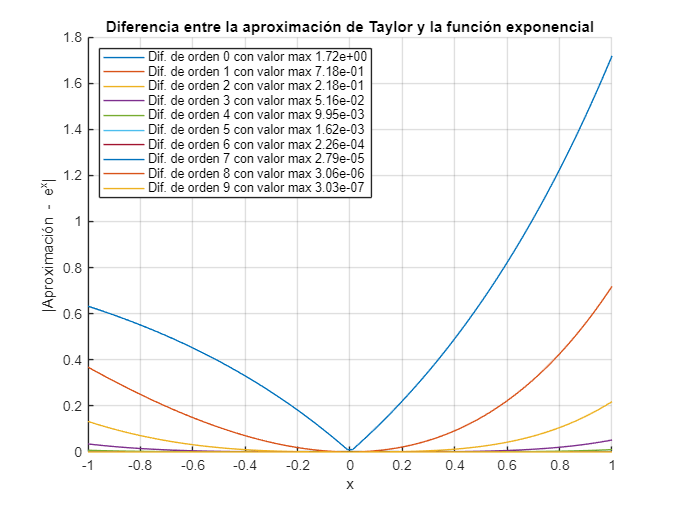



% Inicializar la figura para las diferencias
figure;
hold on;

% Calcular y graficar las diferencias entre la aproximación y la función real
for i = 0:n
    % Calcular la aproximación de Taylor de orden i
    taylor_aprox = zeros(size(x));
    for k = 0:i
        taylor_aprox = taylor_aprox + (x.^k) / factorial(k);
    end

    % Calcular la diferencia
    diferencia = abs(taylor_aprox - exp(x));

    % Graficar la diferencia
    plot(x, diferencia, 'DisplayName', sprintf('Dif. de orden %d con valor max %.2e', i,max(diferencia)));
end

% Añadir etiquetas y leyenda a la figura de diferencias
xlabel('x');
ylabel('|Aproximación - e^x|');
title('Diferencia entre la aproximación de Taylor y la función exponencial');
legend('Location', 'northwest');
grid on;
hold off;